% This is the testing file for scan conversion

fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Single checkerboard
% B = zeros(h,w);
% B(1:2:h,1:2:w) = ones(ceil(h/2),ceil(w/2));
% B(2:2:h,2:2:w) = ones(floor(h/2),floor(w/2))

% Double checkerboard
% B = zeros(h,w);
% B(1:4:h,1:4:w) = ones(ceil(h/4),ceil(w/4));
% B(1:4:h,2:4:w) = ones(ceil(h/4),floor(w/4));
% B(2:4:h,1:4:w) = ones(floor(h/4),ceil(w/4));
% B(2:4:h,2:4:w) = ones(floor(h/4),floor(w/4));
% 
% B(3:4:h,3:4:w) = ones(ceil(h/4),ceil(w/4)-1);
% B(3:4:h,4:4:w) = ones(ceil(h/4),floor(w/4));
% B(4:4:h,3:4:w) = ones(floor(h/4),ceil(w/4)-1);
% B(4:4:h,4:4:w) = ones(floor(h/4),floor(w/4))


% Make block
a = 1000

a =         1000


b = 2000

b =         2000


c = 6

c =      6


d = 12

d =     12



B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

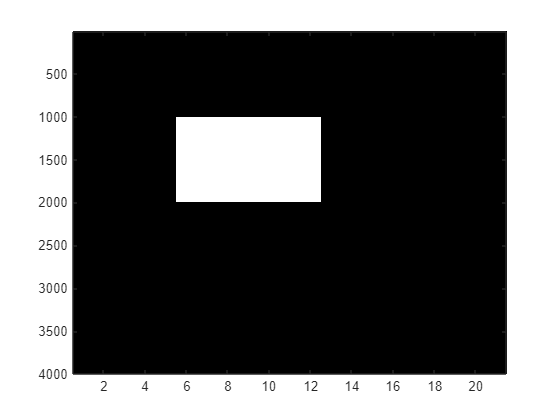


B = B';

figure
colormap(gray)
imagesc(B')


% All ones to view beams
% B = ones(h,w);

imager = 101;
imagec = 201;
ishiftr = floor(imager/2);
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

% Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas; % have spearate lookups for image and for beams??



%precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;


%precompute image rvals
rvals = zeros(imager,imagec);
for rr=1:imager
    for cc=1:imagec
        r = rr-1;
        c = cc - ishiftc - 1;
        rvals(rr,cc) = sqrt(r^2+c^2)/100;
    end
end
rvals;


% for px = 1:imagec
%     for py = 1:imager
%         r = rvals(py,px);
%         n = floor(r*Fs/c);
% 
%         theta = thetas(py,px);
%         k = floor(sin(theta)/2*Fs/fc);
%         kk = k + shift;
%         if (n < h) && (kk < w)
%             blah = B(n,kk);
%         end
%     end
% end
% n
% k
% blah

image = zeros(imager,imagec);


rfpp = (imager-1)/rs(end,1)

rfpp =    4.402509077973718


cfpp = (imagec/2-1)/rs(end,1)

cfpp =    4.380496532583850



aspectRatio = cfpp/rfpp

aspectRatio =    0.995000000000000




%Put things in beams onto image
tic
for kk = 1:w
    k = kk-shift;
    for n = 1:h
        r = rs(n,kk);
        theta = thetas(n,kk);

        y = floor(r*cos(theta)*rfpp);
        x = round(r*sin(theta)*cfpp);

        image(y+1,x+1+ishiftc) = B(kk,n);
    end
end
time = toc

time =    0.014741800000000


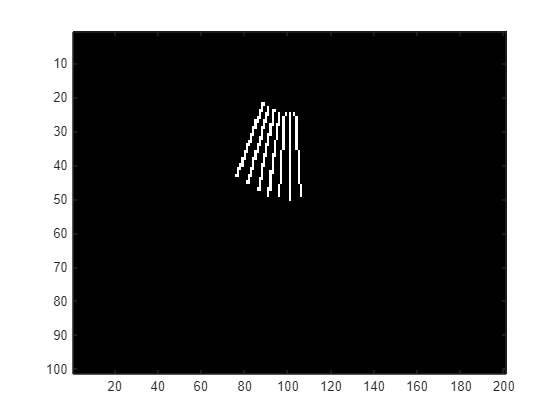

%his time is 0.0466669 but also interpolates



%image = ones(imager,imagec)-image;

figure
colormap(gray)
imagesc(image)


% Now, need to interpolate
image_interp = image;
max_distance = rs(end,1);


tic
for pc = 1:imagec
    for pr = 1:imager
        
        px = (pc-1-ishiftc)/cfpp;
        py = (pr-1)/rfpp;

        rp = sqrt(px^2+py^2);

        if (rp <= .99*max_distance)
            thetap_test = atan(pc/pr);
            thetap = atan(px/py);

            if (px ~= 0)
                kp = sin(thetap)/2*Fs/fc;
            else
                kp =  0;
            end
        
            np = rp/C*Fs;
            n = floor(np)+1;    
            k = floor(kp);
            kk = k+11;                                               
            if (kp ~= k)
                k1 = k+1;
                
                kk1 = k1+11;
        
                
                n1 = n+1;
        
                r = rs(n,1);
                r1 = rs(n1,1);
                dr = r1-r;
        
                theta = thetas(1,kk);
                theta1 = thetas(1,kk1);
                dtheta = theta1-theta;
        
                beta = (rp - r)/dr;
                alpha = (thetap - theta)/dtheta;
        
                image_interp(pr,pc) = (1-beta)*((1-alpha)*B(kk,n)+alpha*B(kk1,n)) + beta*((1-alpha)*B(kk,n1) + alpha*B(kk1,n1));
            else
                image_interp(pr,pc) = B(kk,n);
            end
        else
            image_interp(pr,pc) = 0;
        end

    end
end
toc

Elapsed time is 0.016454 seconds.


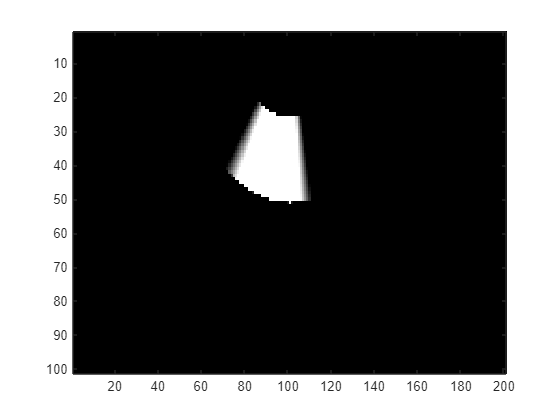


% okay, well already faster


figure
colormap(gray)
imagesc(image_interp)


image_interp;

% compare
B = B*36;

tic
test_image = scan_conversion(B, 21, 4000, 1, 100)

max_pixel =     10


test_image =     10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

toc

Elapsed time is 0.026994 seconds.


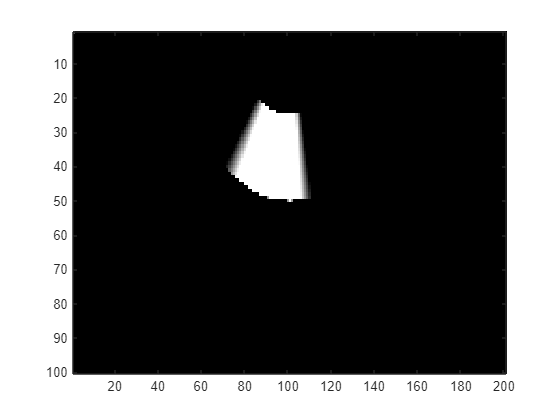


figure
colormap(gray)
imagesc(test_image)

% Figuring out data thing

load sc_image.mat -mat

sc_image

sc_image =   10.000000000000000                   0                   0                   0                   0                   0   6.925880318377913   6.578934899681581  15.438304508223858   4.588324612610002   2.497821835239469   4.538842389941527   1.830506383574379   1.304526653867186   1.786396936046741   1.611697727810480   1.542607697650314   2.552942541497841   1.798914582175006   0.802909638459034   0.836785335421597   1.188300468783487   1.003752215667698   0.470179942662890   0.291966750314886   0.907859656498260   0.794958223648718   0.190008850308847   0.879154789742691   0.549693155088129   0.583171538433274   0.466108218279640   0.640872056916673   0.253554006008627   0.918922802718231   1.395771942886959   0.674295163117886   0.887582387441056   1.195540789112901   2.449219502551708   0.717741209022740   1.134528382644665   1.775078346821175   1.925550440276383   5.583349172848036   3.966183791996426   0.678491762360046   3.277777665353687   0.334165986779212   0.4204

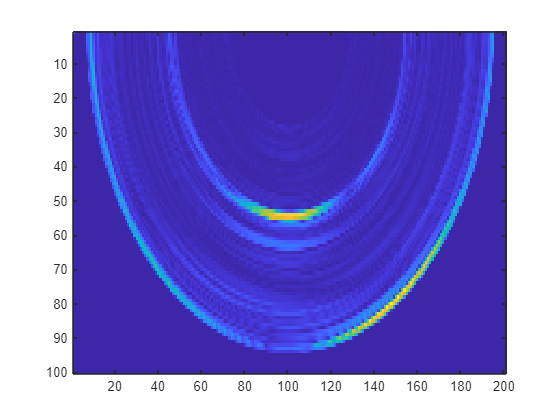


figure
imagesc(sc_image)

% Figuring out data thing

load Mag_image.mat -mat

Mag_image

Mag_image =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

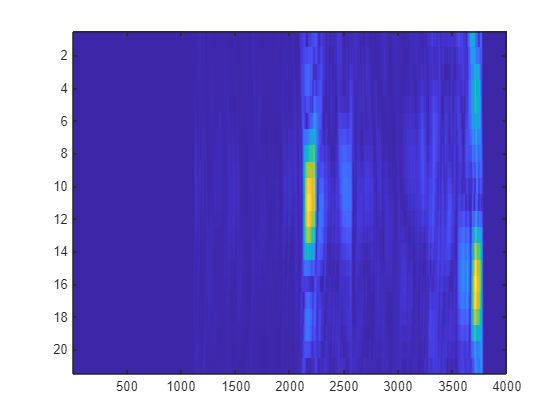


figure
imagesc(Mag_image)


length(Mag_image)

ans =         4000


height(Mag_image)

ans =     21



length(B)

ans =         4000


height(B)

ans =     21


% Turning it into a function
fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Make block
a = 1000

a =         1000


b = 2000

b =         2000


c = 6

c =      6


d = 12

d =     12



B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     


B = B';

figure
colormap(gray)
imagesc(B')


imager = 101;
imagec = 201;
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

% Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas; % have spearate lookups for image and for beams??



%precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

rfpp = (imager-1)/rs(end,1)

rfpp =    4.402509077973718


cfpp = (imagec/2-1)/rs(end,1)

cfpp =    4.380496532583850



aspectRatio = cfpp/rfpp

aspectRatio =    0.995000000000000




max_distance = max(max(rs))

max_distance =   22.714320000000001




% Run Function and Display
tic
image = scan_conversion1(B, 11, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance);
toc

Elapsed time is 0.009560 seconds.



figure
colormap(gray)
imagesc(image)





function image_interp = scan_conversion1(Mag_image, beam_index_shift, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance)
    image_interp = zeros(imager,imagec);
    
    for pc = 1:imagec
        for pr = 1:imager
            
            px = (pc-1-ishiftc)/cfpp;
            py = (pr-1)/rfpp;
    
            rp = sqrt(px^2+py^2);
    
            if (rp <= .99*max_distance)
                thetap = atan(px/py);
    
                if (px ~= 0)
                    kp = sin(thetap)/2*Fs/fc;
                else
                    kp =  0;
                end
            
                np = rp/C*Fs;
                n = floor(np)+1;    
                k = floor(kp);
                kk = k+11;                                               
                if (kp ~= k)
                    k1 = k+1;
                    
                    kk1 = k1+beam_index_shift;   
                    n1 = n+1;
            
                    r = rs(n,1);
                    r1 = rs(n1,1);
                    dr = r1-r;
            
                    theta = thetas(1,kk);
                    theta1 = thetas(1,kk1);
                    dtheta = theta1-theta;
            
                    beta = (rp - r)/dr;
                    alpha = (thetap - theta)/dtheta;
            
                    image_interp(pr,pc) = (1-beta)*((1-alpha)*Mag_image(kk,n)+alpha*Mag_image(kk1,n)) + beta*((1-alpha)*Mag_image(kk,n1) + alpha*Mag_image(kk1,n1));
                else
                    image_interp(pr,pc) = Mag_image(kk,n);
                end
            else
                image_interp(pr,pc) = 0;
            end
    
        end
    end
end

% Turning it into a FAST function
fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Make block
a = 1000

a =         1000


b = 2000

b =         2000


c = 6

c =      6


d = 12

d =     12



B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     


B = B';

figure
colormap(gray)
imagesc(B')


imager = 100;
imagec = 201;
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

rfpp = (imager-1)/rs(end,1)

rfpp =    4.358483987193981


cfpp = (imagec/2-1)/rs(end,1)

cfpp =    4.380496532583850



max_distance = max(max(rs))

max_distance =   22.714320000000001



% ============================= %

% ##### - Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas;

% ##### - Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% ##### - Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% ##### - Precomute px, py, rp, thetap
Pxy = zeros(imager, imagec, 2);
Rpvals = zeros(imager, imagec);
Thetapvals = zeros(imager, imagec);
Kpvals = zeros(imager, imagec);
KNvals = zeros(imager,imagec,2);

Alphas = zeros(imager,imagec);
Betas = zeros(imager,imagec);

for pc = 1:imagec
    for pr = 1:imager
        % Establish x and y
        px = (pc-1-ishiftc)/cfpp;
        py = (pr-1)/rfpp;        
        Pxy(pr,pc,1) = px;
        Pxy(pr,pc,2) = py;

        % Establish rp and thetap
        rp = sqrt(px^2+py^2);
        Rpvals(pr,pc) = rp;

        thetap = atan(px/py);
        Thetapvals(pr,pc) = thetap;

        % Next, kp, kk, and n
        if (px ~= 0)
            kp = sin(thetap)/2*Fs/fc;
        else
            kp =  0;
        end
        Kpvals(pr,pc) = kp;
          
        k = floor(kp);
        kk = k+shift;
        n = floor(np)+1;  

        KKNvals(pr,pc,1) = kk;
        KKNvals(pr,pc,2) = n;

        % Then, calculate alphas and betas 
        % TODO need to split into alpha and beta seperately
        if (kp==k)
            alpha = 0;
            beta = 0;
        else
            r = rs(n,1);
            r1 = rs(n+1,1);
            dr = r1-r;
    
            theta = thetas(1,kk);
            theta1 = thetas(1,kk+1);
            dtheta = theta1-theta;
            
            alpha = (thetap - theta)/dtheta;
            beta = (rp - r)/dr;  
        end

        Alphas(pr,pc) = alpha;
        Betas(pr,pc) = beta;




    end
end
Pxy(:,:,2);

Alphas;
Betas;


% now, make complex data structure according to image... want all four beam
% values, alpha, and beta
% wait... but don't have it, so have to figure out how to do the math
% let's skip all the edges....
% No, its on beams :(
image = zeros(imager,imagec);
%image(2:imager-1,2:imagec-1) = (1-Betas).*((1-Alphas).*Mag_image(1:image,n)+alpha*Mag_image(kk1,n)) + beta*((1-alpha)*Mag_image(kk,n1) + alpha*Mag_image(kk1,n1))





% =================================== %
% Run Function and Display
aspectRatio = cfpp/rfpp

aspectRatio =    1.005050505050505


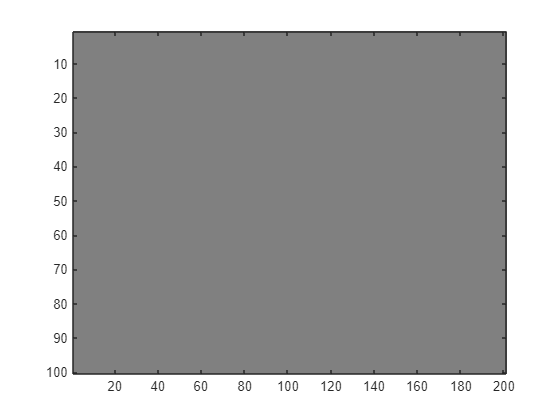



figure
colormap(gray)
imagesc(image)



% tic
% image = scan_conversion_fast(B, 11, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance, Pxy);
% toc

function image_interp = scan_conversion_fast(Mag_image, beam_index_shift, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance, Pxy)
    image_interp = zeros(imager,imagec);
    
    for pc = 1:imagec
        for pr = 1:imager
            
            px = Pxy(pr,pc,1);
            py = Pxy(pr,pc,2);
    
            rp = sqrt(px^2+py^2);
    
            if (rp <= .99*max_distance)
                thetap = atan(px/py);
    
                if (px ~= 0)
                    kp = sin(thetap)/2*Fs/fc;
                else
                    kp =  0;
                end
            
                np = rp/C*Fs;
                n = floor(np)+1;    
                k = floor(kp);
                kk = k+11;                                               
                if (kp ~= k)
                    k1 = k+1;
                    
                    kk1 = k1+beam_index_shift;   
                    n1 = n+1;
            
                    r = rs(n,1);
                    r1 = rs(n1,1);
                    dr = r1-r;
            
                    theta = thetas(1,kk);
                    theta1 = thetas(1,kk1);
                    dtheta = theta1-theta;
            
                    beta = (rp - r)/dr;
                    alpha = (thetap - theta)/dtheta;
            
                    image_interp(pr,pc) = (1-beta)*((1-alpha)*Mag_image(kk,n)+alpha*Mag_image(kk1,n)) + beta*((1-alpha)*Mag_image(kk,n1) + alpha*Mag_image(kk1,n1));
                else
                    image_interp(pr,pc) = Mag_image(kk,n);
                end
            else
                image_interp(pr,pc) = 0;
            end
    
        end
    end
end

% Better making it vector
fc = 10000;
Fs = 200000;
C = 1136;
h = 4000;
w = 21;
shift = 11;

% Make block
a = 1000

a =         1000


b = 2000

b =         2000


c = 6

c =      6


d = 12

d =     12



B = zeros(h,w);
B(a:b,c:d) = ones(b-a+1,d-c+1)

B =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     


B = B';

figure
colormap(gray)
imagesc(B')


imager = 100;
imagec = 201;
ishiftc = floor(imagec/2);
image = zeros(imager,imagec);

rfpp = (imager-1)/rs(end,1)

rfpp =    4.358483987193981


cfpp = (imagec/2-1)/rs(end,1)

cfpp =    4.380496532583850



max_distance = max(max(rs))

max_distance =   22.714320000000001



% ============================= %



% Single checkerboard
% B = zeros(h,w);
% B(1:2:h,1:2:w) = ones(ceil(h/2),ceil(w/2));
% B(2:2:h,2:2:w) = ones(floor(h/2),floor(w/2))

% Double checkerboard
B = zeros(h,w);
B(1:4:h,1:4:w) = ones(ceil(h/4),ceil(w/4));
B(1:4:h,2:4:w) = ones(ceil(h/4),floor(w/4));
B(2:4:h,1:4:w) = ones(floor(h/4),ceil(w/4));
B(2:4:h,2:4:w) = ones(floor(h/4),floor(w/4));

B(3:4:h,3:4:w) = ones(ceil(h/4),ceil(w/4)-1);
B(3:4:h,4:4:w) = ones(ceil(h/4),floor(w/4));
B(4:4:h,3:4:w) = ones(floor(h/4),ceil(w/4)-1);
B(4:4:h,4:4:w) = ones(floor(h/4),floor(w/4))

B =      1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0
     0     0     1     1     0     0     1     1     0     0     1     1     0     0     1     1     0     

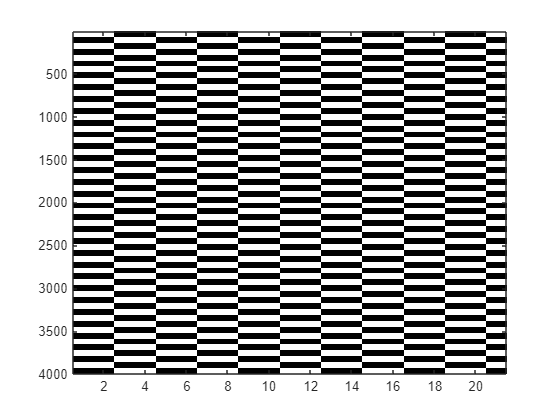



% Make block
% a = 1000
% b = 2000
% c = 6
% d = 12
% 
% B = zeros(h,w);
% B(a:b,c:d) = ones(b-a+1,d-c+1)

B = B';

figure
colormap(gray)
imagesc(B')


% create 
image = zeros(imager,imagec);
%image(2:end-1,2:end-1);
%B(KKNvals(1:end-2,1:end-2,1));

% ============================= %

% ##### - Precompute thetas
thetas = zeros(h,w);
for kk=1:w
    k = kk-shift;
    thetas(:,kk) = asin(2*k*fc/Fs);
end
thetas;

% ##### - Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% ##### - Precompute rs
rs = zeros(h,w);
for n=0:h-1
    rs(n+1,:) = n*C/Fs;
end
rs;

% ##### - Precomute px, py, rp, thetap
Pxy = zeros(imager, imagec, 2);
Rpvals = zeros(imager, imagec);
Thetapvals = zeros(imager, imagec);
Kpvals = zeros(imager, imagec);
KNvals = zeros(imager,imagec,2);

Alphas = zeros(imager,imagec);
Betas = zeros(imager,imagec);

for pc = 1:imagec
    for pr = 1:imager
        % Establish x and y
        px = (pc-1-ishiftc)/cfpp;
        py = (pr-1)/rfpp;        
        Pxy(pr,pc,1) = px;
        Pxy(pr,pc,2) = py;

        % Establish rp and thetap
        rp = sqrt(px^2+py^2);
        Rpvals(pr,pc) = rp;

        thetap = atan(px/py);
        Thetapvals(pr,pc) = thetap;

        % Next, kp, kk, and n
        if (px ~= 0)
            kp = sin(thetap)/2*Fs/fc;
        else
            kp =  0;
        end
        Kpvals(pr,pc) = kp;
          
        k = floor(kp);
        kk = k+shift;

        np = rp/C*Fs;
        n = floor(np)+1;  

        if (n >= length(B))
            n = length(B)-1;
        end

        KKNvals(pr,pc,1) = kk;
        KKNvals(pr,pc,2) = n;

        if (kk >= 21)
            KK1N1vals(pr,pc,1) = kk;
        else
            KK1N1vals(pr,pc,1) = kk+1;
        end

        if (n >= 4000)
            KK1N1vals(pr,pc,2) = n;
        else
            KK1N1vals(pr,pc,2) = n+1;
        end


        % Then, calculate alphas and betas 
        % TODO need to split into alpha and beta seperately
        if (kp==k)
            alpha = 0;
            beta = 0;
        else
            r = rs(n,1);
            r1 = rs(n+1,1);
            dr = r1-r;
    
            theta = thetas(1,kk);
            theta1 = thetas(1,kk+1);
            dtheta = theta1-theta;
            
            alpha = (thetap - theta)/dtheta;
            beta = (rp - r)/dr;  
        end

        Alphas(pr,pc) = alpha;
        Betas(pr,pc) = beta;




    end
end
Pxy(:,:,2);

Alphas;
Betas;





KKNvals(1,100,1),KKNvals(1,100,2)

ans =      1


ans =     41


sub2ind([22 4000],KKNvals(1,100,1),KKNvals(1,100,2))

ans =    881


B(881)

ans =      0


KKNvals(:,:,1)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

KKNvals(:,:,2)

ans =         3999        3979        3939        3899        3859        3819        3778        3738        3698        3658        3618        3577        3537        3497        3457        3417        3377        3336        3296        3256        3216        3176        3135        3095        3055        3015        2975        2934        2894        2854        2814        2774        2733        2693        2653        2613        2573        2533        2492        2452        2412        2372        2332        2291        2251        2211        2171        2131        2090        2050
        3999        3980        3939        3899        3859        3819        3779        3738        3698        3658        3618        3578        3538        3497        3457        3417        3377        3337        3296        3256        3216        3176        3136        3095        3055        3015        2975        2935        2895        2854        2814        2774        2

sub2ind([22 4000],KKNvals(:,:,1),KKNvals(:,:,2))

ans =        87957       87517       86637       85757       84877       83997       83095       82215       81335       80455       79575       78673       77793       76913       76033       75153       74273       73371       72491       71611       70731       69851       68949       68069       67189       66309       65429       64527       63647       62767       61887       61007       60105       59225       58345       57465       56585       55705       54803       53923       53043       52163       51283       50381       49501       48621       47741       46861       45959       45079
       87957       87539       86637       85757       84877       83997       83117       82215       81335       80455       79575       78695       77815       76913       76033       75153       74273       73393       72491       71611       70731       69851       68971       68069       67189       66309       65429       64549       63669       62767       61887       61007       60



% B_temp = [B_temp zeros(22, 1)]

% B_temp = B;


ind_bkn = sub2ind([22 4001],KKNvals(:,:,1),KKNvals(:,:,2));
ind_bk1n = sub2ind([22 4000],KKNvals(:,:,1)+1,KKNvals(:,:,2));
ind_bkn1 = sub2ind([22 4000],KKNvals(:,:,1),KKNvals(:,:,2)+1);
ind_bk1n1 = sub2ind([22 4000],KKNvals(:,:,1)+1,KKNvals(:,:,2)+1);
Bkn = B_temp(ind_bkn)

Bkn =      0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0
     0     1     1     1     1     1     0     0     0     0     0     0     0     0     0 

Bk1n = B_temp(ind_bk1n)

Bk1n =      0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0
     0     1     1     1     1     1     0     0     0     0     0     0     0     0     0

Bkn1 = B_temp(ind_bkn1)

Bkn1 =      0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0
     0     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0

Bk1n1 = B_temp(ind_bk1n1)

Bk1n1 =      0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0
     0     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1     0     0     


BMAM = (1-Betas).*(1-Alphas);
BMA = (1-Betas).*Alphas;
BAM = Betas.*(1-Alphas);
BA = Betas.*Alphas;

%image = Betas

tic
B_temp = [B; zeros(1,4000)];
image=BMAM.*B_temp(ind_bkn)+BMA.*B_temp(ind_bk1n) + BAM.*B_temp(ind_bkn1) + BA.*B_temp(ind_bk1n1);
toc

Elapsed time is 0.005728 seconds.


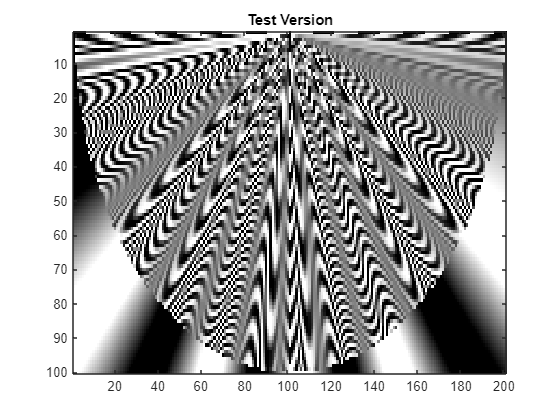



figure
colormap(gray)
imagesc(image)
title("Test Version")


% Run Function and Display
tic
image = scan_conversion1(B, 11, cfpp, rfpp, thetas, rs, ishiftc, Fs, fc, imagec, imager, C, max_distance);
toc

Elapsed time is 0.008931 seconds.


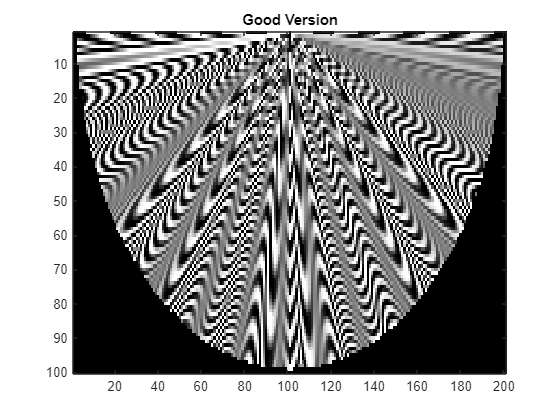


figure
colormap(gray)
imagesc(image)
title("Good Version")

v = magic(5)

v =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


v(sub2ind([5 5],[1 1; 3 3],[2 4; 2 4]))

ans =     24     8
     6    20



B(sub2ind([21 4000],KKNvals(1:end-2,1:end-2,1),KKNvals(1:end-2,1:end-2,2)))

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 